%calculating the mean first passage time analytically/numerically 
%to investigate effect of invader toehold length on RNA/DNA TMSD kinetics

b = 20 %define branch migration domain length

b = 20

%g = 2 %define invader toehold length

R = 1.987/1000 % universal gas constant in kcal/K/mol 

R = 0.0020

temp = 298.15 %temperature in K

temp = 298.1500

%free energy parameters
dGassoc = 2.6*R*temp

dGassoc = 1.5403

dGbp = -2.52*R*temp

dGbp = -1.4929

dGrd = -1*R*temp

dGrd = -0.5924

dGp = 3.6*R*temp

dGp = 2.1327

dGbm = 7.4*R*temp

dGbm = 4.3839

%absolute rate constant
k_bp = 5.4*10^7

k_bp = 54000000

k_eff = zeros(1,15)

k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = zeros(1, 15)

first_pass_time =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%loop through invader toehold lengths 
for g = 1:15

    %define forward and reverse transition rates
    k_AA = 0;
    k_AB1 = k_bp * exp(-dGassoc/(R*temp)) * (5*10^-8)
    k_B1A = k_bp * exp((dGbp + dGrd)/(R*temp))
    k_BC1ij = k_bp;
    k_BC1ji = k_bp * exp((dGbp + dGrd)/(R*temp))
    k_C1f = k_bp * exp(-(dGbm + dGp)/(R*temp))
    k_Cf = k_bp * exp(-dGbm/(R*temp))
    k_Cr = k_bp * exp(-(dGbm - dGrd)/(R*temp))
    k_CD = k_bp * exp(-dGbm/(R*temp));
    k_DC = 0 
    k_DD = 1
    
    %create arrays of forward and reverse transition rates
    if g == 1
        Kf = [k_DD, k_CD, repmat(k_Cf, [1, b-2]), k_C1f, k_AB1]
        Kb = [k_DC, repmat(k_Cr, [1, b-2]), k_Cr, k_B1A, k_AA]
        
    else
        Kf = [k_DD, k_CD, repmat(k_Cf, [1, b-2]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
        Kb = [k_DC, repmat(k_Cr, [1, b-2]), k_Cr, k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
    end
    
    Pn_j0 = zeros(1,numel(Kf))
    Pn_j0 (1) = 0
    %calculate flux between each state
    for Pn = 2:numel(Kf)
        Pn_j0(Pn)  = 1/Kf(Pn) + Kb(Pn-1)/Kf(Pn)*Pn_j0(Pn-1)
    end

    first_pass_time (g) = sum(Pn_j0) %calculate first passage time
    k_eff (g) = 1/(first_pass_time (g)*(5*10^-8)) %calculate effective rate constant
end

k_AB1 = 0.2005

k_B1A = 1.5984e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

Kf = 	1.0e+04 *

    0.0001    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    0.0902    0.0000


Kb = 	1.0e+06 *

         0    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    1.5984         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 = 	1.0e+-4 *

         0    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.3030    0.4144         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.3030    0.4144    0.4554         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.3030    0.4144    0.4554    0.4705         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.3030    0.4144    0.4554    0.4705    0.4760         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018         0


Pn_j0 = 	1.0e+04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.3986


first_pass_time = 	1.0e+04 *

    1.3986         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+03 *

    1.4300         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

Kf = 	1.0e+07 *

    0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    0.0000


Kb = 	1.0e+06 *

         0    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    1.5984    1.5984         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 = 	1.0e+-4 *

         0    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.3030    0.4144         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.3030    0.4144    0.4554         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.3030    0.4144    0.4554    0.4705         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.3030    0.4144    0.4554    0.4705    0.4760         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0


Pn_j0 = 	1.0e+-4 *

         0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001  418.9510


first_pass_time =     1.3986    0.0419         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     0.1430    4.7738         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb =          0    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    1.5984    1.5984    1.5984         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000   17.3873


first_pass_time =     1.3986    0.0419    0.0017         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     0.0014    0.0477    1.1501         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    1.5984    1.5984    1.5984    1.5984         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    5.5012


first_pass_time =     1.3986    0.0419    0.0017    0.0006         0         0         0         0         0         0         0         0         0         0         0


k_eff =     0.0014    0.0477    1.1501    3.6338         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    1.5984    1.5984    1.5984    1.5984    1.5984         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    5.1494


first_pass_time =     1.3986    0.0419    0.0017    0.0006    0.0005         0         0         0         0         0         0         0         0         0         0


k_eff =     0.0014    0.0477    1.1501    3.6338    3.8819         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    5.1390


first_pass_time =     1.3986    0.0419    0.0017    0.0006    0.0005    0.0005         0         0         0         0         0         0         0         0         0


k_eff =     0.0014    0.0477    1.1501    3.6338    3.8819    3.8898         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    5.1387


first_pass_time =     1.3986    0.0419    0.0017    0.0006    0.0005    0.0005    0.0005         0         0         0         0         0         0         0         0


k_eff =     0.0014    0.0477    1.1501    3.6338    3.8819    3.8898    3.8900         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    5.1387


first_pass_time =     1.3986    0.0419    0.0017    0.0006    0.0005    0.0005    0.0005    0.0005         0         0         0         0         0         0         0


k_eff =     0.0014    0.0477    1.1501    3.6338    3.8819    3.8898    3.8900    3.8900         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    5.1387


first_pass_time =     1.3986    0.0419    0.0017    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005         0         0         0         0         0         0


k_eff =     0.0014    0.0477    1.1501    3.6338    3.8819    3.8898    3.8900    3.8900    3.8900         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


first_pass_time =     1.3986    0.0419    0.0017    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005         0         0         0         0         0


k_eff =     0.0014    0.0477    1.1501    3.6338    3.8819    3.8898    3.8900    3.8900    3.8900    3.8900         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


first_pass_time =     1.3986    0.0419    0.0017    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005         0         0         0         0


k_eff =     0.0014    0.0477    1.1501    3.6338    3.8819    3.8898    3.8900    3.8900    3.8900    3.8900    3.8900         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


first_pass_time =     1.3986    0.0419    0.0017    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005         0         0         0


k_eff =     0.0014    0.0477    1.1501    3.6338    3.8819    3.8898    3.8900    3.8900    3.8900    3.8900    3.8900    3.8900         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


first_pass_time =     1.3986    0.0419    0.0017    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005         0         0


k_eff =     0.0014    0.0477    1.1501    3.6338    3.8819    3.8898    3.8900    3.8900    3.8900    3.8900    3.8900    3.8900    3.8900         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


first_pass_time =     1.3986    0.0419    0.0017    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005         0


k_eff =     0.0014    0.0477    1.1501    3.6338    3.8819    3.8898    3.8900    3.8900    3.8900    3.8900    3.8900    3.8900    3.8900    3.8900         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.3030    0.4144    0.4554    0.4705    0.4760    0.4781    0.4788    0.4791    0.4792    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793    0.4793         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


first_pass_time =     1.3986    0.0419    0.0017    0.0006    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005


k_eff =     0.0014    0.0477    1.1501    3.6338    3.8819    3.8898    3.8900    3.8900    3.8900    3.8900    3.8900    3.8900    3.8900    3.8900    3.8900


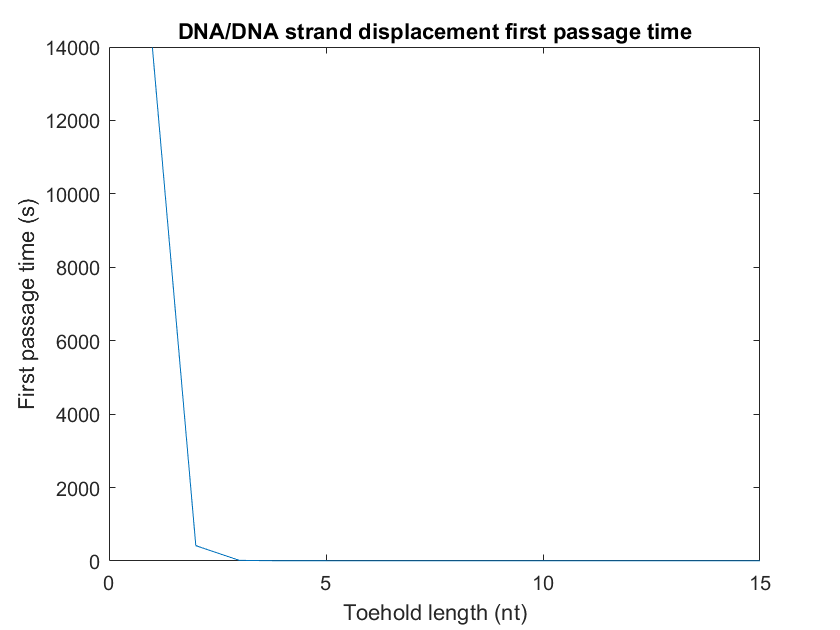

plot(1:15, first_pass_time)
ylabel('First passage time (s)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement first passage time')

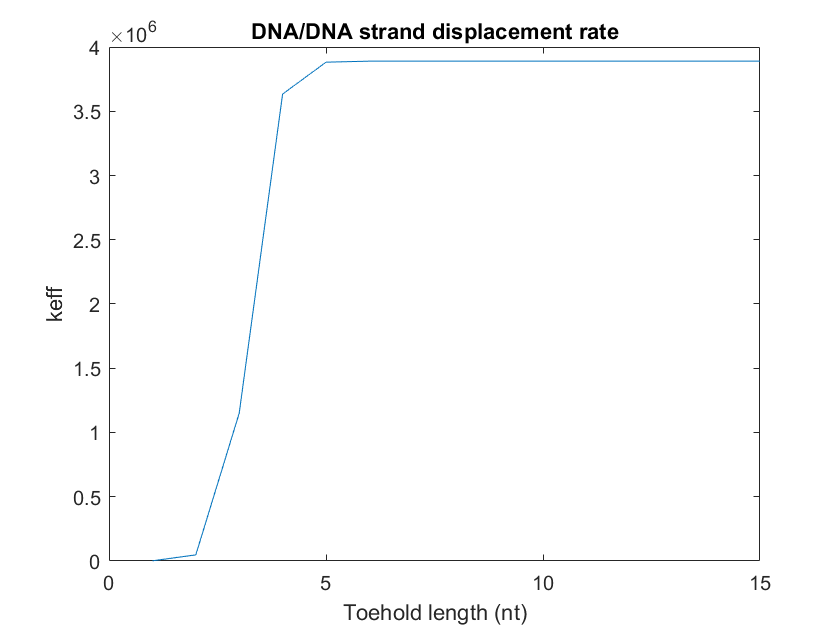


plot(1:15, k_eff)
xlabel('Toehold length (nt)')
ylabel('keff')
title('DNA/DNA strand displacement rate')

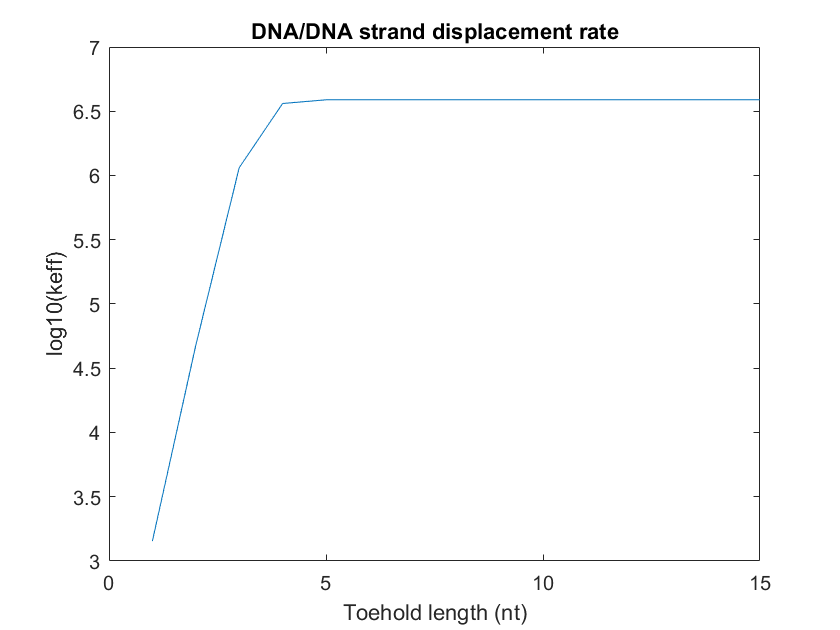


plot(1:15, log10(k_eff))
xlabel('Toehold length (nt)')
ylabel('log10(keff)')
title('DNA/DNA strand displacement rate')  